##  Included in Workspace

close all; clear all;clc
cd('C:\BitBucketRepositories\Spatial Context KAC Association\MatlabCode')

% Parameters
fs =2000;

% List of sound files
cwd ='D:\Data\DCLDE2013\DCLDE_2013_10Channel\Day1'; % testing on one day
cwd = 'D:\Data\DCLDE2013\DCLDE_2013_10Channel\All'; % running on all days
file_list=(  dir(fullfile(cwd, '*.aif')));

% Folder containing the neural network output
detectionsLocation = 'C:\BitBucketRepositories\Spatial Context KAC Association\NeuralNetworkOutput'

detectionsLocation = 'C:\BitBucketRepositories\Spatial Context KAC Association\NeuralNetworkOutput'

NNoutput = dir(fullfile(detectionsLocation, '*.txt'))

NNoutput = 7×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum




%% All the validation files
truthFiles = dir('C:\BitBucketRepositories\Spatial Context KAC Association\TruthFiles\*.csv');


% Reference and total number of channels
ref_chan=10;
num_chan=10;

% Load DCLDE meta data
dclde_2013_meta = xlsread('D:/DCL2013_NEFSC_SBNMS_200903_metadata.xlsx');

## From the Neural Network output, add the necessary file contents to allign with Raven selection tables

detectionsOut =[]; % empty variable to stack across selection table days
for ii = 1:length(NNoutput)

    
    fname = fullfile(NNoutput(ii).folder, NNoutput(ii).name)
    detections = readtable(fname);
    detections.streamSampleStart = round(detections.BeginTime_s_*fs)+(24*(ii-1)*60*60*fs)+1;
    detections.streamSampleStop = detections.streamSampleStart+(fs*2);
    detections = sortrows(detections,'streamSampleStart','ascend');
    detections.date = ones([height(detections), 1])*datenum(NNoutput(ii).name(end-11:end-4), 'yyyymmdd');
    detections.BeginTime_s_= detections.BeginTime_s_+((ii-1)*24*60*60);
    detections.EndTime_s_= detections.EndTime_s_+((ii-1)*24*60*60);
    detections.Selection= detections.Selection+size(detectionsOut,1);
    chanCall=ones(1,10);
    
    detectionsOut = [detectionsOut; detections];
    
    
end

fname = 'C:\BitBucketRepositories\Spatial Context KAC Association\NeuralNetworkOutput\upcall_seltab_20090328.txt'

fname = 'C:\BitBucketRepositories\Spatial Context KAC Association\NeuralNetworkOutput\upcall_seltab_20090329.txt'

fname = 'C:\BitBucketRepositories\Spatial Context KAC Association\NeuralNetworkOutput\upcall_seltab_20090330.txt'

fname = 'C:\BitBucketRepositories\Spatial Context KAC Association\NeuralNetworkOutput\upcall_seltab_20090331.txt'

fname = 'C:\BitBucketRepositories\Spatial Context KAC Association\NeuralNetworkOutput\upcall_seltab_20090401.txt'

fname = 'C:\BitBucketRepositories\Spatial Context KAC Association\NeuralNetworkOutput\upcall_seltab_20090402.txt'

fname = 'C:\BitBucketRepositories\Spatial Context KAC Association\NeuralNetworkOutput\upcall_seltab_20090403.txt'


detectionsOut = sortrows(detectionsOut,'streamSampleStart','ascend');
detections = detectionsOut;
clear detectionsOut


## Load the Metadata associated with each hydrophone. 

load the data and inspect the hydrophone geometry. A structure of the hydrophone information is then created for the association process

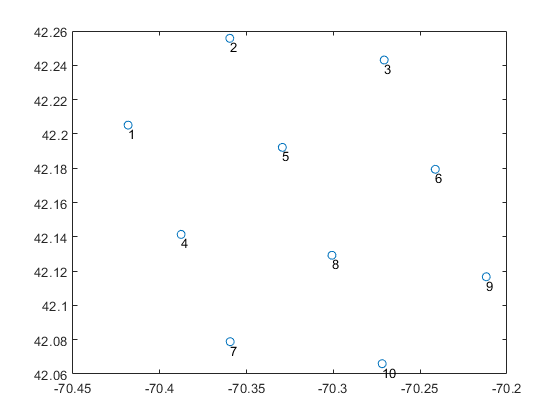


% Create labels for plotting locations (undocumented function)
labels=sprintfc('%d',1:10);

plot(dclde_2013_meta(:,12), dclde_2013_meta(:,11), 'o')
text(dclde_2013_meta(:,12), dclde_2013_meta(:,11),labels,'VerticalAlignment','top','HorizontalAlignment','left')


% Convert the meta data to a structure in the format that the
% GPL/localisation code expects

hydrophone_struct= struct();
for ii=1:size(dclde_2013_meta,1)
    hydrophone_struct(ii).name = num2str(dclde_2013_meta(ii,1));
    hydrophone_struct(ii).location = dclde_2013_meta(ii,[11:12]);
    hydrophone_struct(ii).depth= abs(dclde_2013_meta(ii, 13));
    hydrophone_struct(ii).channel=ii;
    
end




## Create a list of all the soundfiles and pull the starttime of each file from the filename


file_listTable = struct2table(file_list); % List of files

% Convert character to matlab date for start time
file_listTable.MatlabDate = cell2mat(vertcat(cellfun(@(x) datenum(x(end-18:end-4), 'yyyymmdd_HHMMSS'), ...
    file_listTable.name, 'UniformOutput', false)));

% Samples into the entire stream (full day for testing or multiple days if running on full dataset)
file_listTable.SampleStrt = fs*60*60*24*(file_listTable.MatlabDate-floor(min(file_listTable.MatlabDate)));

% Seconds inot the stream
file_listTable.SecStart = (file_listTable.MatlabDate-floor(file_listTable.MatlabDate))*60*60*24;
file_listTable.SampStop =file_listTable.SampleStrt+(15*60*fs);



## Set up the meta data into a structure

%get the x corr times between hydrophone 10 (primary) and others
for ii=1:num_chan
    % distance between the primary and secondary
    dist(ii) = vdist2(hydrophone_struct(10).location(1),...
        hydrophone_struct(10).location(2),...
        hydrophone_struct(ii).location(1),...
        hydrophone_struct(ii).location(2));
end
hydDelay = dist/1350; % delay between each hdyrophone pair in seconds

% convert delays from seconds to samples
hydDelay = round(hydDelay * fs);

% get max delay
% Add some slack, if this works a more systematic approach will be warented
max_delay = max(hydDelay)+2; 

##  Create the associations using KAC code

This bit creates the asscoations of calls between the reference channel and those on the adjacent channels using Kathy Cortipassi cross correlation code. Returns tables for each returned variable wthere the rows are the number of detections on the reference channel and the columns are the number of hydrophones in the array minus 1. Blank/NA cells indicate where no associations were present.

Delays - time in seconds between the reference and other detections on other channels

Dex - Index of each of the detections that has been associated

crossScores -cross correlation scores between the referene detection and the adjacent ones

arrivalArray- arrival time (in seconds) of each of the detections


delays = nan(sum((detections.Channel==10)), 10); 
dex = delays;
crossScores = dex;
arrivalArray = dex;
detectionsRef =detections(detections.Channel==ref_chan,:);


% Primary detections
for ii =1:height(detectionsRef)
    
    [delays(ii,:), dex(ii,:), crossScores(ii,:),val] = ...
        createAssociations(detections, ii, file_listTable,hydDelay, ref_chan, fs);
    
    if ~isempty(val)
        valueout(ii)=val;
    end
    dex(ii,ref_chan)=detectionsRef.Selection(ii);
    
    ii;
 
end


beginBuffpts =

     []


beginBuffpts =

     []


beginBuffpts =

     []


beginBuffpts =

     []


beginBuffpts =

     []


beginBuffpts =

     []


beginBuffpts =

     []


beginBuffpts =

     []


beginBuffpts =

     []


beginBuffpts =

     []


beginBuffpts =

     []


beginBuffpts =

     []


beginBuffpts =

     []


beginBuffpts =

     []


beginBuffpts =

     []


beginBuffpts =

     []


beginBuffpts =

     []


beginBuffpts =

     []


beginBuffpts =

     []


beginBuffpts =

     []


beginBuffpts =

     []


beginBuffpts =

     []


beginBuffpts =

     []


beginBuffpts =

     []


beginBuffpts =

     []


beginBuffpts =

     []


beginBuffpts =

     []


beginBuffpts =

     []


beginBuffpts =

     []


beginBuffpts =

     []


beginBuffpts =

     []


beginBuffpts =

     []


beginBuffpts =

     []


beginBuffpts =

     []


beginBuffpts =

     []


beginBuffpts =

     []


beginBuffpts =

     []


beginBuffpts =

     []


beginBuffpt

## Remove associations where multiple primary channel detections were linked to secondary detections

Because association is based on cross correlation only one deteciton on a reference channel may be correlated to multiple calls on the primary channel. See dex rows 45:51 (45:51,:)

dex(45:51,5:10)


%%%%%%%%%% This actually doesn't seem to help at all but should be done regardles. 


for jj =1:9
    
    [counts, ids] = groupcounts(dex(~isnan(dex(:,jj)),jj));
    doubleBooked =ids(counts>1);
    
    % Step through the double booked values, find the highest correlationa call
    % and for all othe rprimary calls, remove the association
    
    for ii=1:length(doubleBooked)
        
        callId = doubleBooked(ii);
        primaryCalldexs = find(dex(:,jj)==callId);
        
        % get the cross correlation scores
        corrscores = vertcat(valueout(primaryCalldexs).all_pk_xcorr_raw);
        
        % index of the strongest correlation
        [~, keepIdx] =max(corrscores(:,jj));
        primaryCalldexs(keepIdx)=[];
        
        % Allow that one to stay but clear out the arrival array, dex, and
        % cross scores for the remaining double booked detections
        delays(primaryCalldexs,jj)=nan;
        dex(primaryCalldexs,jj)=nan;
        crossScores(primaryCalldexs,jj)=nan;
        
        
    end
end

%house keeping
clear counts ids doubleBooked callId primaryCalldexs corrscores keepIdx


## Prep the validation data

Raven selection tables with all annotations of the reference channel. Simulation structure is only used for the temporal context (as in linking acoustic encounters)




truthStream =[];
for ii=1:length(truthFiles)
    
    truthtemp = readtable(fullfile(truthFiles(ii).folder, truthFiles(ii).name));
    truthtemp=truthtemp(:,1:7);
    
    
    if ii>1
        truthtemp.Selection=truthtemp.Selection+height(truthStream);
    end
    
    truthtemp.mstart = datenum(truthFiles(ii).name(7:14), 'yyyymmdd')+truthtemp.BeginTime_s_/86400;
    truthtemp.mend = datenum(truthFiles(ii).name(7:14), 'yyyymmdd')+truthtemp.EndTime_s_/86400;
    truthtemp.mid = (truthtemp.mend+truthtemp.mstart)/2;
    truthtemp.Sec = (truthtemp.mstart-min(truthtemp.mstart))*60*60*24+(ii-1)*24*60*60;
    truthtemp.DetectorScore = zeros([height(truthtemp) 1 ]);
    truthtemp.BeginTime_s_= truthtemp.BeginTime_s_+((ii-1)*24*60*60);
    truthtemp.EndTime_s_= truthtemp.EndTime_s_+((ii-1)*24*60*60);
    truthStream=[truthStream; truthtemp];
    clear truthtemp
    ii;
end

truth = truthStream;
clear truthStream truthtemp truthFiles


%% Set up the simulation structure
arrivalArray = detectionsRef.BeginTime_s_*ones(1,10)+delays;
arrivalArray(:,10)=detectionsRef.BeginTime_s_;

simStruct = struct();
simStruct.arrivalArray = [arrivalArray(:,ref_chan) arrivalArray(:,1:end-1)];
simStruct.TDOA_vals = delays;


simStruct.fs =fs;
simStruct.PosUncertsigma = 0.0004^2 +.1^2 + .3^2; % seconds see EM Nosal 20
simStruct.PosUncertsigma = 0.0067^2 +.003^2 + .25^2; % seconds see EM Nosal 20- R position, ssp, arrival time
simStruct.drift = 0.25; % clock drift uncertainty
simStruct.c =1500;  % speed of sound
simStruct.truncateKm=18; % replaced by half normal function, previously maximum detection distance
simStruct.maxEltTime = 30*60; % Maximum elapsed time between detections to make another encounter
simStruct.s = 3;% maximum swim speed of the animal in m/s

refChanScores =detections.Score(detections.Channel==ref_chan);
simStruct.RefScores = refChanScores;

% Match the truth files to the 'pruned' detections to establish what the
% truth is
simStruct.dex = dex;
[simStruct.pruned truth]= validateDetection(truth, simStruct, ref_chan);
% Three different apporaches


%% Create the results field to look at precision and recall as a function
% of the max elapsed time and similarity threshold



**Simple Clustering. **

For detections with cross correlation scores above the threshold, assign assign the scores to the highest score in the association groups


allscore = zeros(size(dex,1), num_chan);

allDex = [dex(:,1:9), detectionsRef.Selection];

% where we have scores
idxReplace = find(~isnan(allDex));

for ii=1:length(idxReplace)
    
    allscore(idxReplace(ii)) = detections.Score(detections.Selection == dex(idxReplace(ii)));
end

%%



% Do the detector onnly
simStruct.RefScores = detectionsRef.Score;
[ detector,~] = PrecisionRecalAssocOnly(simStruct, truth);
Results.Baseline(1,1) = detector;

        hold on
        plot(Results.Baseline(1,1).Recall,...
            Results.Baseline(1,1).Precision,...
            'k+','Linewidth',2)
        xlabel('Recall'); ylabel('Precision')
        
crossScoreThresh = [.001,.05,.1,.2];

Markers = {'-o','-.','-+','-*', '->', '-o','-.','-+','-*', '->'};
sizeVal = [2, 6,4,2,2,2, 6,4,2,2,2, 6,4,2,2];
markercounter=1;
markercounter=1
    for jj =1:length(crossScoreThresh)
        
        keepScores = allscore(:,1:9);

        % Remove all scores below the correlation score
        keepScores(crossScores<=crossScoreThresh(jj)) = 0;
        keepScores(keepScores==0)=nan;
        
        % Update the reference scores
        newRef = max([keepScores,detectionsRef.Score],[],2)
        newRef =  mean([keepScores,detectionsRef.Score],2, 'omitnan')

        simStruct.RefScores=  newRef
        % Updatet the 'truth' scores
        [simStruct.pruned newTruth]= validateDetection(truth, simStruct, ref_chan);
        
        [detector,~] = PrecisionRecalAssocOnly(simStruct, newTruth);
        Results.AssocClusters(1,jj) = detector;
        
        
        hold on
        plot(Results.AssocClusters(1,jj).Recall,...
            Results.AssocClusters(1,jj).Precision, ...
            Markers{markercounter},...
            'MarkerSize',sizeVal(markercounter))
        markercounter=markercounter+1
        
        
    end
    
    %cluster in time
    
